data = readtable('synthetic_wind_storage_data_10000.csv');


min_max_values = [min(data{:,2:end}); max(data{:,2:end})]; 
disp(array2table(min_max_values, 'VariableNames', data.Properties.VariableNames(2:end), 'RowNames', {'Min', 'Max'}));

           WindSpeed_m_s_    LoadVariation_MW_    FrequencyDeviation_Hz_    BatterySOC___
           ______________    _________________    ______________________    _____________

    Min        8.3182             91.488                  1.6988                33.44    
    Max         15.43             108.28                  2.0555               66.677    



data = readtable('synthetic_wind_storage_data_10000.csv');

head(data)

    Time_s_    WindSpeed_m_s_    LoadVariation_MW_    FrequencyDeviation_Hz_    BatterySOC___
    _______    ______________    _________________    ______________________    _____________

       0           12.074             99.309                  1.8707                51.09    
       1           12.106             100.19                  1.8832               50.924    
       2           11.303             100.01                  1.8766               49.482    
       3           11.774             99.117                  1.8621               48.035    
       4           11.447              100.2                  1.8857               47.821    
       5           11.817             98.905                    1.86                52.85    
       6           11.596             100.14                  1.8933         

data_norm = normalize(data{:, 2:end}, 'range');  % Skip first column (Time)

wind_fis_final = readfis('wind_fis_fixed.fis');
showrule(wind_fis_final) % To verify rules are correctly added

ans = 27×147 char array
    '1. If (Wind_Speed is WS_Low) and (Load_Variation is LV_Low) and (Frequency_Deviation is FD_Low) then (Power_Regulation_Command is PR_Up) (1)       '
    '2. If (Wind_Speed is WS_Low) and (Load_Variation is LV_Low) and (Frequency_Deviation is FD_Med) then (Power_Regulation_Command is PR_Up) (1)       '
    '3. If (Wind_Speed is WS_Low) and (Load_Variation is LV_Low) and (Frequency_Deviation is FD_High) then (Power_Regulation_Command is PR_Up) (1)      '
    '4. If (Wind_Speed is WS_Low) and (Load_Variation is LV_Med) and (Frequency_Deviation is FD_Low) then (Power_Regulation_Command is PR_Neutral) (1)  '
    '5. If (Wind_Speed is WS_Low) and (Load_Variation is LV_Med) and (Frequency_Deviation is FD_Med) then (Power_Regulation_Command is PR_Up) (1)       '
    '6. If (Wind_Speed is WS_Low) and (Load_Variation is LV_Med) and (Frequency_Deviation is FD_High) then (Power_Regulation_Command is PR_Up) (1)      '
    '7. If (Wind_Speed is WS_Low) and (Load_Variatio

test_input = [12, 150, 0.2];  % Wind Speed, Load Variation, Frequency Deviation
output = evalfis(test_input, wind_fis_final);

disp(['Power Regulation Output: ', num2str(output), ' MW']);

Power Regulation Output: -188.5326 MW


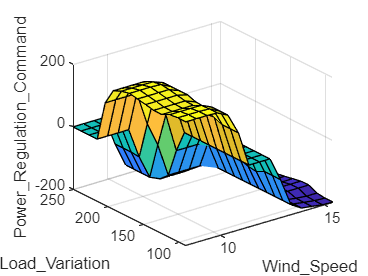

gensurf(wind_fis_final);